# **OTTIMIZZAZIONE PORTAFOGLIO MEDIA-CV@R CON MODELLO LP**

**LETTURA DATI E SET DEI PARAMETRI**

Per implementare il problema di ottimizzazione di portafoglio mean-CV@R abbiamo scelto di utilizzare i dati storici di 9 indici: 'CSCO', 'DELL', 'EBAY', 'HPQ', 'IBM', 'INTC', 'MSFT', 'ORCL', 'YHOO'.

%se il codice dovesse non runnare bene, disattivare i comandi di plot delle
%copule nella sezione finale
clear all; close all; clc;
rng('default')

Lettura dati

load CAPMuniverse.mat
symbol = {'CSCO','DELL','EBAY','HPQ','IBM','INTC','MSFT','ORCL','YHOO'};
nAsset = numel(symbol);

Estraiamo i prezzi e i returns dei vari indici :

datiR = AssetsTimeTable{:,symbol};
% datiP = ret2tick(datiR);

Plottiamo l'istogramma dei returns :

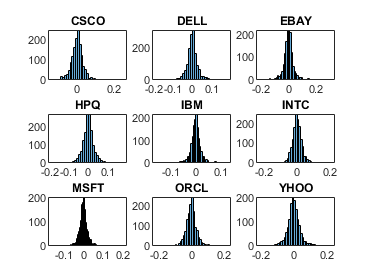

figure
plotAssetHist(symbol,datiR);

Estraiamo media e covarianza dei returns che ci serviranno per generare gli scenari :

mu = mean(datiR);
sigma = cov(datiR);

Settiamo i prezzi iniziali (P0) a un vettore di tutti 1

P0 = ones(size(datiR,2),1);

Settiamo la ricchezza iniziale e la ricchezza minima che vorremmo raggiungere alla maturità; inoltre per generare la frontiera efficiente prendiamo 50 ricchezze minime diverse comprese tra un range di valori.

W0 = 500;
Nport=50;

Settiamo alpha:

alpha = 0.05;

Dopo abbiamo plottato l'istogramma degli asset scenarios  (con 2000 Scenari), per vedere se la distribuzione dei returns simulati fosse simile a quella reale:

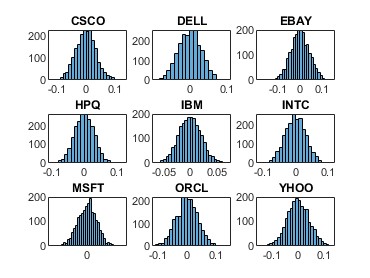

 figure
 AssetScenarios = mvnrnd(mu,sigma,2000);
 plotAssetHist(symbol,AssetScenarios);

**OTTIMIZZAZIONE PORTAFOGLIO E CONFRONTO TRA CON IL CV@R ESATTO RICAVATO CON LA FORMULA DELLA NORMALE MULTIVARIATA**

***VALUTAZIONE IMPATTO DEL NUMERO DEGLI SCENARI***

Per valutare l'impatto del numero degli scenari sulla qualità del portafoglio ottenuto abbiamo testato il modello rispettivamente con 500 , 1000, 2000 , 5000 e 10000 scenari e calcoliamo l'errore medio su N prove per ogni caso.

Nprove=100;
Nscenarios = [500, 1000 , 2000, 5000, 10000];
WTmin=500; % ricchezza minima che vogliamo ottenere
errScen = zeros(length(Nscenarios),1);

for i = 1:length(Nscenarios)
    
    mediaScen = 0;
    
       for j = 1:Nprove
           
            AssetScenarios = mvnrnd(mu,sigma,Nscenarios(i));

            [money,quantity,var,cvar]=solveRetProb(W0,AssetScenarios,WTmin,alpha,P0,1);
            cvaresatto = cvarnormal( W0, mu ,sigma, quantity , alpha , 1 ,P0');
            mediaScen = mediaScen+cvar ;
            
       end
       
            errScen(i) = abs((mediaScen/Nprove)-cvaresatto)/abs(cvaresatto);
end

Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving proble

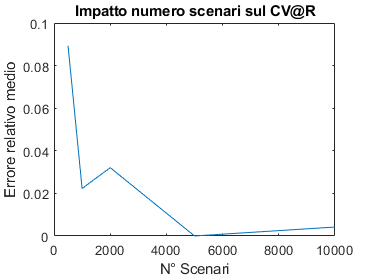


figure
plot(Nscenarios,errScen);
title('Impatto numero scenari sul CV@R')
xlabel('N° Scenari')
ylabel('Errore relativo medio')

Dal plot si evince chiaramente che l'errore medio relativo tra il cvar calcolato col nostro modello LP e quello ricavato con la formula della normale multivariata diminuisce all'aumentare del numero degli scenari. Inoltre possiamo vedere che otteniamo un errore medio relativo basso e ciò fa pensare che il nostro sia un buon modello.

***CALCOLO FRONTIERA EFFICIENTE ***

D'ora in avanti utilizzeremo 2000 scenari per effettuare i vari test e anche per calcolare la frontiera efficiente.          

AssetScenarios = mvnrnd(mu,sigma,Nscenarios(3));
ret = zeros(Nport,1);
cvarvec = zeros(Nport,1);
cvaresatto = zeros(Nport,1);
cvarerr = zeros(Nport,1); %errore relativo tra cvar del modello e il cvar esatto calcolato con la normale
qta = zeros(nAsset,Nport);

Per ottenere la frontiera efficiente ci siamo calcolati 50 portafogli ottimali facendo variare la ricchezza minima tra un range di valori ammissibili.



WTarget = W0*(linspace(min(mean(AssetScenarios)), max(mean(AssetScenarios)),Nport)+1);

for j = 1 : Nport
    
[money,quantity,var,cvar]=solveRetProb(W0,AssetScenarios,WTarget(j),alpha,P0,0);
 
ret(j) = mean(AssetScenarios) * quantity ;
 
cvarvec(j) = cvar;

cvaresatto(j) = cvarnormal( W0, mu ,sigma, quantity , alpha , 1 ,P0');

cvarerr(j) = abs(cvarvec(j)-cvaresatto(j))/abs(cvaresatto(j));

qta(:,j) = quantity;

end

Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving problem using linprog.

Optimal solution found.


Solving proble

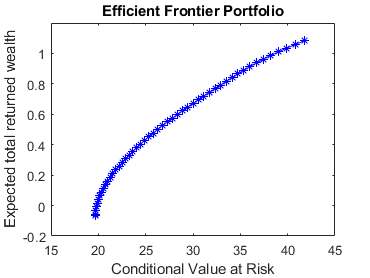


figure
plot(cvarvec,ret,'b-*')
title('Efficient Frontier Portfolio')
xlabel('Conditional Value at Risk')
ylabel('Expected total returned wealth')

**VISUALIZZAZIONE ISTOGRAMMA DISTRIBUZIONE RETURNS DEL PORTAFOGLIO**

In questa sezione vogliamo visualizzare il V@R e il CV@R sulla distribuzione dei returns simulati al variare dei 50 portafogli diversi ottenuti nella sezione precedente.

figure
nBin = 50;
PortNum=50

PortNum = 50

plotCVaRHistOpt(alpha,W0,WTarget(PortNum),0, P0, AssetScenarios, nBin);

Solving problem using linprog.

Optimal solution found.



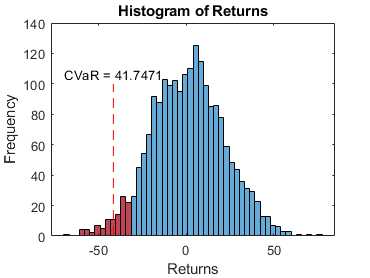

hold off

# **OTTIMIZZAZIONE PORTAFOGLIO MEDIA-CV@R USANDO TOOLBOX DI MATLAB**

In questa sezione abbiamo confrontato i risultati ottenuti dal nostro modello LP con quelli ottenuti sfruttando il toolbox di Matlab. In particolare, abbiamo confrontato le frontiere efficienti e le stime del CV@R in due modi diversi:

- Abbiamo calcolato i portafogli della frontiera efficiente sfruttando solamente gli strumenti del toolbox e li abbiamo confrontati con ciò che abbiamo ottenuto con il nostro Modello.

- Abbiamo stimato il CV@R e la frontiera efficiente con gli strumenti del Financial Toolbox, ma gli abbiamo passato i pesi ottimali ottenuti dal nostro modello.

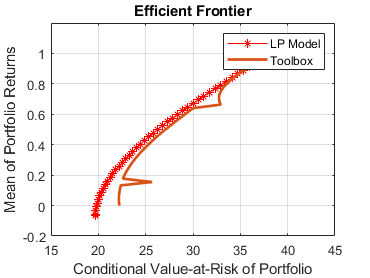

p = PortfolioCVaR('Scenarios', AssetScenarios);
p = setDefaultConstraints(p);
p = setBudget(p,W0,W0);
p = setProbabilityLevel(p,1-alpha); 


pcvar = estimatePortRisk(p,qta);
pret = estimatePortReturn(p,qta);


figure

plot(cvarvec,ret,'r*-');
hold on 
prischio = plotFrontier(p,Nport);
legend('LP Model', 'Toolbox')
hold off

%errore relativo fra le medie del calcolo dei cvar calcolati per la frontiera
%efficiente, dovuto ad una diversa distribuzione dei portafogli utilizzati
%dal toolbox per poter calcolare la frontiera efficiente 
ErroreRelativoToolboxMedio = abs((mean(cvarvec)-mean(prischio)))/abs(mean(prischio))

ErroreRelativoToolboxMedio = 0.0603


%errore relativo fra le stime del cvar ottenuto con il modello LP e con il toolbox; per il calcolo abbiamo 
%usato le stesse quantita ottimali di asset calcolate con il modello LP per
%vedere se il toolbox calcola il CV@R allo stesso modo del modello LP.
ErroreRelativoStimaCvarToolbox = abs(cvarvec-pcvar)./abs(pcvar)

ErroreRelativoStimaCvarToolbox = 	1.0e+-14 *

         0
         0
    0.4518
    0.1983
    0.3593
    0.5898
    0.2131
    0.0881
    0.4016
    0.0346



ErroreRelativoMedioStimaCvarToolbox = mean(abs(cvarvec - pcvar)./abs(pcvar))

ErroreRelativoMedioStimaCvarToolbox = 2.6581e-15

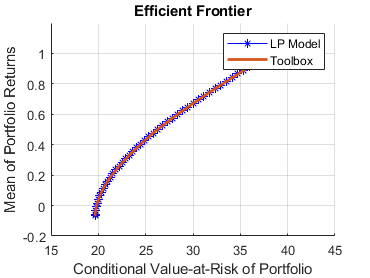


figure

%plot confronto frontiera efficiente con CV@R e Returns medio totale
%calcolati dal modello lp VS. calcolati dalle funzioni del toolbox,
%basandosi sullo stesso vettore di pesi(vedere variabili pcvar e pcret)
hold on
plot(cvarvec,ret,'b*-');
plotFrontier(p,pcvar,pret);
legend('LP Model', 'Toolbox')

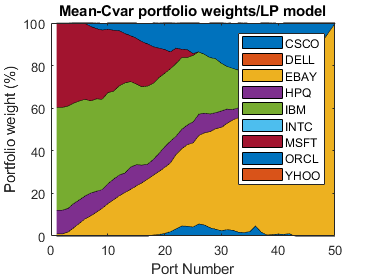

%plot dei pesi di portfolio al variare dei portafogli generati nel calcolo
%della frontiera efficiente con il modello LP
figure
weights = qta.*P0/W0;
plotWeight(weights, symbol, 'Mean-Cvar portfolio weights/LP model')

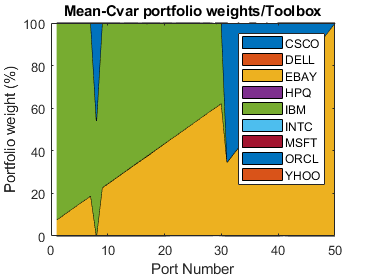


%plot dei pesi di portfolio al variare dei portafogli generati nel calcolo
%della frontiera efficiente con il Toolbox
figure
pwgt = estimateFrontier(p,Nport);
plotWeight(pwgt.*P0/W0,symbol, 'Mean-Cvar portfolio weights/Toolbox')


%istogramma distribuzione dei returns simulati e posizione CV@R per un
%portfolio scelto della frontiera efficiente ottenuta dal Financial Toolbox
plotCVaRHist(p,pwgt,AssetScenarios,PortNum,nBin);

Dai plot si evince che nel primo caso descritto ad inizio sezione notiamo una leggera differenza nei valori del CV@R e, inoltre, le frontiere efficienti coincidono in alcuni tratti, mentre in altri sono visibili delle differenze; ciò potrebbe essere dovuto al fatto che le frontiere efficienti sono ottenute con meccanismi diversi: nel modello LP facciamo variare il  vincolo di ricchezza minima alla maturità per calcolare portafogli efficienti diversi, mentre il Financial Toolbox di Matlab utilizza altri metodi.

D'altra parte, se analizziamo i risultati ottenuti nel secondo caso descritto ad inizio sezione, otteniamo dei risultati identici, sia per quanto riguarda il CV@R che per la frontiera efficiente.

# **SIMULAZIONI OUT OF SAMPLE**

In questa sezione testiamo il modello con simulazioni Out of sample, valutandone le prestazioni con scenari diversi, valutandone eventualmente il deterioramento rispetto al campione quando ci sono eventuali errori di modello(scenari provenienti da diverse distribuzioni di probabilità) o di stima(parametri caratterizzanti la distribuzione degli scenari diversi).

rng('default')

AssetScenarios = mvnrnd(mu,sigma,Nscenarios(3));

WTmin = 500*(1 + mean(AssetScenarios));

[money,quantity,var,cvar]=solveRetProb(W0,AssetScenarios,WTmin,alpha,P0,0);

Solving problem using linprog.

Optimal solution found.




WT = P0'.*(1+mean(AssetScenarios))*quantity;

**1. MEDIA E MATRICE DI VAR COV OUT OF SAMPLE = MEDIA E MATRICE DI VAR COV IN SAMPLE**


NSimulazioni = 2000;
Nprove = 10;
ErrMedio = 0;
WTsim = zeros(Nprove,1);

for i = 1:Nprove
    
    rng(randi(Nprove*10));
    
    AssetSim=mvnrnd(mu,sigma,NSimulazioni);

    WTsim(i) = P0'.*(1+mean(AssetSim))*quantity;

    ErrMedio = ErrMedio + abs(WTsim(i) - WT)/Nprove;

end

ErrMedioRel  = ErrMedio/abs(WT)

ErrMedioRel = 4.8129e-04

 In questo caso otteniamo un errore medio relativo dell'ordine di 10^-4 (molto piccolo) in accordo con le nostre previsioni , in quanto gli scenari out of sample sono stati simulati con la stessa media e matrice di varianza e covarianza degli scenari in sample.

**2. MEDIA OUT OF SAMPLE != MEDIA IN SAMPLE **

NSimulazioni = 2000;
Nprove = 10;
Nmedie=5;
ErrMedio = zeros(Nmedie,1);
WTsim = zeros(Nprove,1);
muSim = mvnrnd(mu,sigma,1)

muSim =    -0.0351   -0.0157   -0.0430   -0.0384    0.0190   -0.0615   -0.0368   -0.0205    0.0207


gamma=0.15;
for j = 1:Nmedie
    
   for i = 1:Nprove
       
    rng(randi(Nprove*10));
    
    AssetSim=mvnrnd(muSim+(gamma*j),sigma,NSimulazioni);

    WTsim(i) = P0'.*(1+mean(AssetSim))*quantity;

    ErrMedio(j) = ErrMedio(j) + abs(WTsim(i) - WT)/Nprove;

end
end

ErrMedioRel  =ErrMedio/abs(WT)

ErrMedioRel =     0.1053
    0.2552
    0.4048
    0.5546
    0.7045


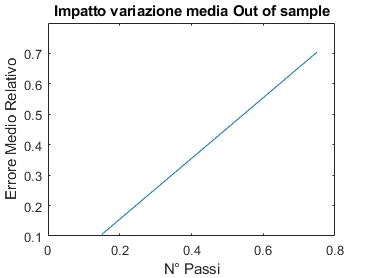


figure
plot( [1:Nmedie]*gamma,ErrMedioRel)
title('Impatto variazione media Out of sample')
xlabel('N° Passi')
ylabel('Errore Medio Relativo')

In questo caso possiamo notare che, tanto più la media out of sample è lontana da quella in sample, tanto più l'errore medio relativo aumenta.

**3. MATRICE DI VAR COV IN SAMPLE != MATRICE DI VAR COV OUT OF SAMPLE**

NSimulazioni = 2000;
Nprove = 10;
NGross = [10 50 100 500 1000];
ErrMedio = zeros(length(NGross),1);
WTsim = zeros(Nprove,1);

%sigmaSim = sigma + 1;

%Modifica alla matrice di varianza-covarianza per renderla diversa da
%quella in sample
ModCov = tril(randn(nAsset));
ModCov = (ModCov + ModCov') - diag(diag(ModCov + ModCov'));

ModVar =  max(abs(eig(ModCov)))*(1 + rand(nAsset,1)).*eye(size(sigma));

sigmaSim = sigma + ModVar + ModCov;

for j=1:length(NGross)

    for i = 1:Nprove
        rng(randi(Nprove*10));
        AssetSim=mvnrnd(mu,NGross(j) *sigmaSim,NSimulazioni);

        WTsim(i) = P0'.*(1+mean(AssetSim))*quantity;

        ErrMedio(j) = ErrMedio(j) + abs(WTsim(i) - WT)/Nprove;

    end
end
ErrMedioRel  =ErrMedio/abs(WT)

ErrMedioRel =     0.1292
    0.3201
    0.4242
    1.0244
    1.5256


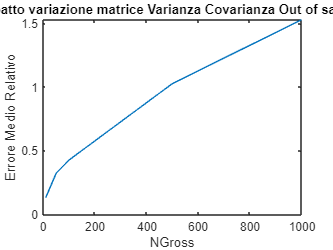


figure
plot(NGross,ErrMedioRel)
title('Impatto variazione matrice Varianza Covarianza Out of sample')
xlabel('NGross')
ylabel('Errore Medio Relativo')

Come nel caso precedente, se aumentiamo il parametro NGross vengono aumentati i valori della nuova matrice di Varianza-Covarianza; di conseguenza, anche i valori dell'errore relativo aumentano.

**4. MODELLO A DUE FATTORI DI RISCHIO CON COPULA DI CLAYTON**

*4.1  In questo caso stimiamo i coefficienti alpha, beta1 e beta2 fittando un modello di regressione lineare *                           

NSimulazioni = 2000;
NTraining = 2000;
Nprove = 10;
ErrMedio = 0;
WTsim = zeros(Nprove,1);

AssetSim = zeros(NSimulazioni,nAsset);



ClayTrain= copularnd("Clayton",2,NTraining);

beta = zeros(nAsset,3);

    for j = 1 : nAsset

        lm = fitlm(ClayTrain,AssetScenarios(:,j));

        beta(j,:) = (lm.Coefficients.Estimate)';

    end

for i = 1:Nprove
    rng(randi(Nprove*10));

    ClaySim = copularnd("Clayton",2,NTraining);
    
     X = [ones(NSimulazioni,1),ClaySim] ;

    AssetSim = (beta*X')';
    
    WTsim(i) = P0'.*(1+mean(AssetSim))*quantity;

    mean(AssetSim);

    ErrMedio = ErrMedio + abs(WTsim(i) - WT)/Nprove;

end

ErrMedioRel  = ErrMedio/abs(WT)

ErrMedioRel = 2.4895e-05

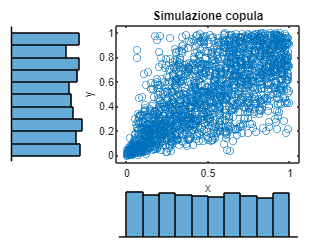


 scatterhist(ClaySim(:,1),ClaySim(:,2));
 title('Simulazione copula');

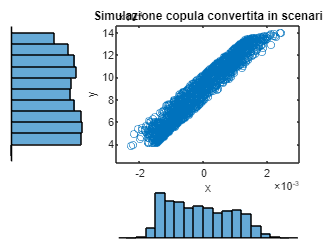


 scatterhist(AssetSim(:,1),AssetSim(:,2));
 title('Simulazione copula convertita in scenari')

Dal valore dell'errore medio relativo molto basso si evince che , utilizzando i coefficienti ottenuti con la regressione lineare , il nostro modello e quello a 2 fattori con copula di Clayton sono molto simili. Ciò è causato dal fatto che, nonostante abbiamo utilizzato un modello di copula a due fattori, la regressione lineare sceglie i parametri che minimizzano lo scarto quadratico tra i fattori e gli scenari degli asset.

*4.2 In questo test invece i coefficienti del modello non vengono stimati con una regressione lineare ma sono stati assegnati da noi per vedere come variassero i risultati.*

NSimulazioni = 2000;
Nprove = 10;
K1 = [-100 -50 1 10 50 100]/50;
K2 = [-60 -20 0.5 5 20 50]/50;
ErrMedio = zeros(length(K1),1);
WTsim = zeros(Nprove,1);


for j = 1:length(K1)
    beta = [mean(AssetScenarios);
    K1(j)*rand(1,nAsset);
    K2(j)*rand(1,nAsset)]';

        for i = 1:Nprove
             rng(randi(Nprove*10));

             ClaySim = copularnd("Clayton",2,NTraining);
    
             X = [ones(NSimulazioni,1),ClaySim] ;

             AssetSim = (beta*X')';
                   
             
              WTsim(i) = P0'.*(1+mean(AssetSim))*quantity;
            
              mean(AssetSim);

              ErrMedio(j) = ErrMedio(j) + abs(WTsim(i) - WT)/Nprove;



end
    end
       
ErrMedioRel  = ErrMedio/abs(WT)

ErrMedioRel =     0.9454
    0.3153
    0.0060
    0.1296
    0.1788
    1.0054


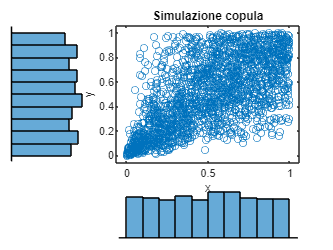


figure
scatterhist(ClaySim(:,1),ClaySim(:,2));
 title('Simulazione copula');

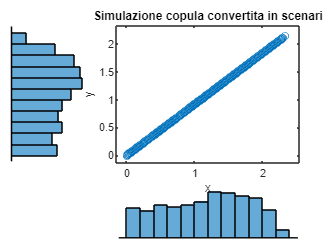


 figure
 scatterhist(AssetSim(:,1),AssetSim(:,2));
 title('Simulazione copula convertita in scenari')

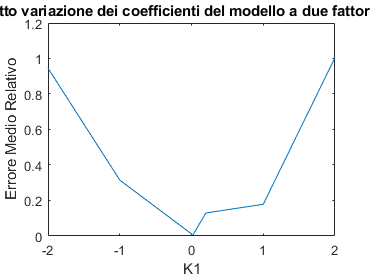


figure
plot(K1,ErrMedioRel)
title('Impatto variazione dei coefficienti del modello a due fattori fattori')
xlabel('K1')
ylabel('Errore Medio Relativo')

Dalla nostra ultima analisi, possiamo notare che se i coefficienti dei fattori di rischio sono molto alti in valore assoluto, l'errore diventa molto grande; d'altra parte, nel caso i due coefficienti siano piccoli in valore assoluto, l'errore diminuisce drasticamente, quindi i risultati tendono ad avvicinarsi a quelli del nostro modello. 